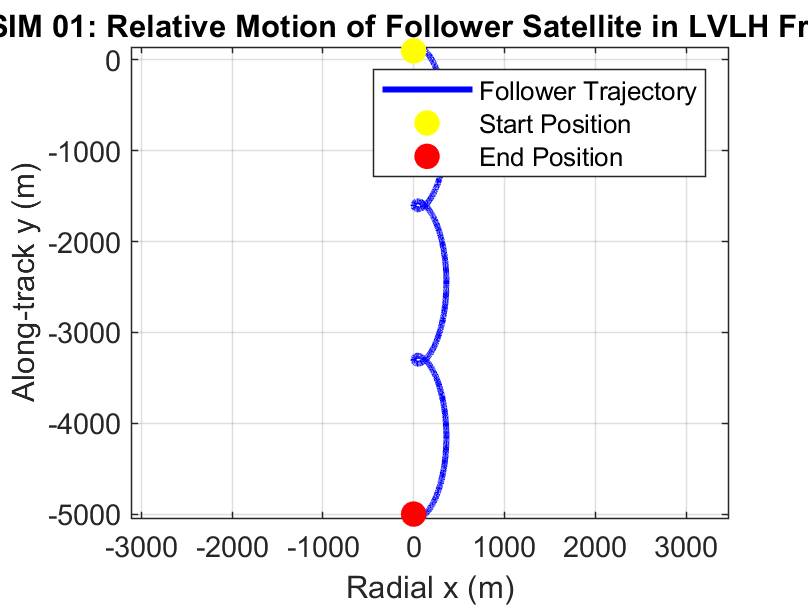

%% ========================================================================
%  SIM_01_TwoSat_PassiveDrift
%  --------------------------------------------------------------
%  - Simulates passive relative motion of a follower satellite
%    with respect to a leader satellite using the Clohessy-Wiltshire (CW)
%    equations in the Local-Vertical Local-Horizontal (LVLH) frame.
%
%  - No control inputs applied (follower drifts naturally).
%  - Motion is integrated over 3 orbits.
%
%  Author: Sabrina Nicacio
% ========================================================================

clc; clear; close all;

%% === PARAMETERS ===
% Define orbital and system parameters
mu = 3.986e14;            % Earth's gravitational parameter (m^3/s^2)
Re = 6371e3;              % Earth radius (m)
alt = 500e3;              % Orbital altitude (m)
a = Re + alt;             % Semi-major axis (m)
n = sqrt(mu / a^3);       % Mean motion (rad/s)

T = 2*pi / n;             % Orbital period (s)
N_orbits = 3;             % Number of orbits to simulate

% Time settings
dt = 1;                   % Time step (s)
tspan = 0:dt:(N_orbits * T); % Total simulation time

%% === INITIAL RELATIVE STATE ===
% State vector: [x; y; z; x_dot; y_dot; z_dot]
% x  = Radial distance (m)
% y  = Along-track distance (m)
% z  = Cross-track distance (m)
% x_dot, y_dot, z_dot = Velocities in respective directions (m/s)
x0 = [0; 100; 0; 0; 0.1; 0];  % 100m ahead in along-track direction, small velocity in y

%% === CLOHESSY-WILTSHIRE EQUATIONS IN MATRIX FORM ===
A = [  0     0     0     1     0     0;
       0     0     0     0     1     0;
       0     0     0     0     0     1;
     3*n^2   0     0     0   2*n     0;
       0     0     0  -2*n     0     0;
       0     0  -n^2    0     0     0];

% Define function handle for numerical integration
cw_dynamics = @(t, x) A * x;

%% === SOLVE USING ODE45 (NUMERICAL INTEGRATION) ===
[t, x] = ode45(cw_dynamics, tspan, x0);

% Transpose solution for easier plotting
x = x';

%% === PLOT RELATIVE MOTION IN LVLH FRAME ===
figure;
plot(x(1,:), x(2,:), 'b', 'LineWidth', 2);
hold on;
plot(x(1,1), x(2,1), 'yo', 'MarkerSize', 8, 'MarkerFaceColor', 'y');  % Start position
plot(x(1,end), x(2,end), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r'); % End position
xlabel('Radial x (m)');
ylabel('Along-track y (m)');
title('SIM 01: Relative Motion of Follower Satellite in LVLH Frame');
legend('Follower Trajectory', 'Start Position', 'End Position');
grid on;
axis equal;

%% === SAVE FIGURE FOR DOCUMENTATION ===
saveas(gcf, 'SIM_01_TwoSat_PassiveDrift.png');  % Save plot as an image


%% === END OF SIMULATION ===
disp('Simulation completed: SIM_01_TwoSat_PassiveDrift');

Simulation completed: SIM_01_TwoSat_PassiveDrift
